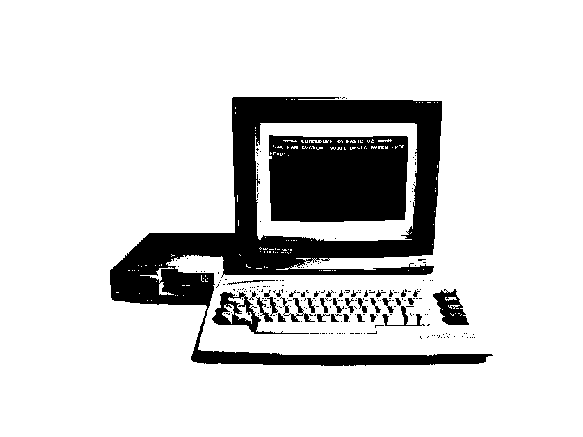

A = double(imread("binary_image.gif"));
imshow(A,[]);


% Horizontal run-length
Arow = reshape(A', 1, []);
cc_row = count_successive(Arow);
result_row = rle(cc_row);
size_rle_row = length(result_row)

size_rle_row = 94417


% Vertical run-length
Acolm = reshape(A, 1, []);
cc_colm = count_successive(Acolm);
result_colm = rle(cc_colm);
size_rle_colm = length(result_colm)

size_rle_colm = 139712

The RLE use an Implementation of an Elias code. It has been implemented to match the table page 144 of the slides provided on the course website, which mean it does not include the superfluous bit as discribed page 142.

function [rbits] = rle(counts_vector)
    rbits = [];
    for i = 1:length(counts_vector)
        intgr = counts_vector(i);
        if(intgr == 1)
            codeword = [0, 0];
        elseif(intgr == 2)
            codeword = [0, 1, 0];
        elseif(intgr == 3)
            codeword = [0, 1, 1];
        else
            binary = fliplr(de2bi(intgr));
            binary = binary(2:length(binary));
            l = length(binary);
            binary_l = fliplr(de2bi(l));
            last_bit = binary_l(length(binary_l));

            codeword = binary_l(1:length(binary_l)-1);
            if(last_bit == 0)
                codeword = [codeword, 0, 1];
            else
                codeword = [codeword, 1, 0]; 
            end
            
            codeword = [codeword, binary];
        end
        rbits = horzcat(rbits, codeword);
    end
end

function [r] = count_successive(e)
    r = [];
    previous = e(1);
    counter = 1;
    for i = 2:length(e)
        if e(i) == previous
            counter = counter + 1;
        else
            r = [r, counter];
            counter = 1;
            previous = e(i);
        end
    end
    r = [r, counter];
end